% requires guess to find nearest 0 (think TI-84 graphing)
x0 = 1;
x = fsolve(@(x) cos(x) - 0.5 * log(x), x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


disp(x);

    1.4013




% different output values
% fv -> 0 = higher accuracy
% exit should always be 1
[x, fv, exit] = fsolve(@(x) cos(x) - 0.5 * log(x), x0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x = 1.4013

fv = 9.4690e-08

exit = 1

f = @(x) x.^2 .* cos(x);
x1 = fsolve(f,pi)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x1 = 1.5708

x2 = fsolve(f,2*pi)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


x2 = 4.7124

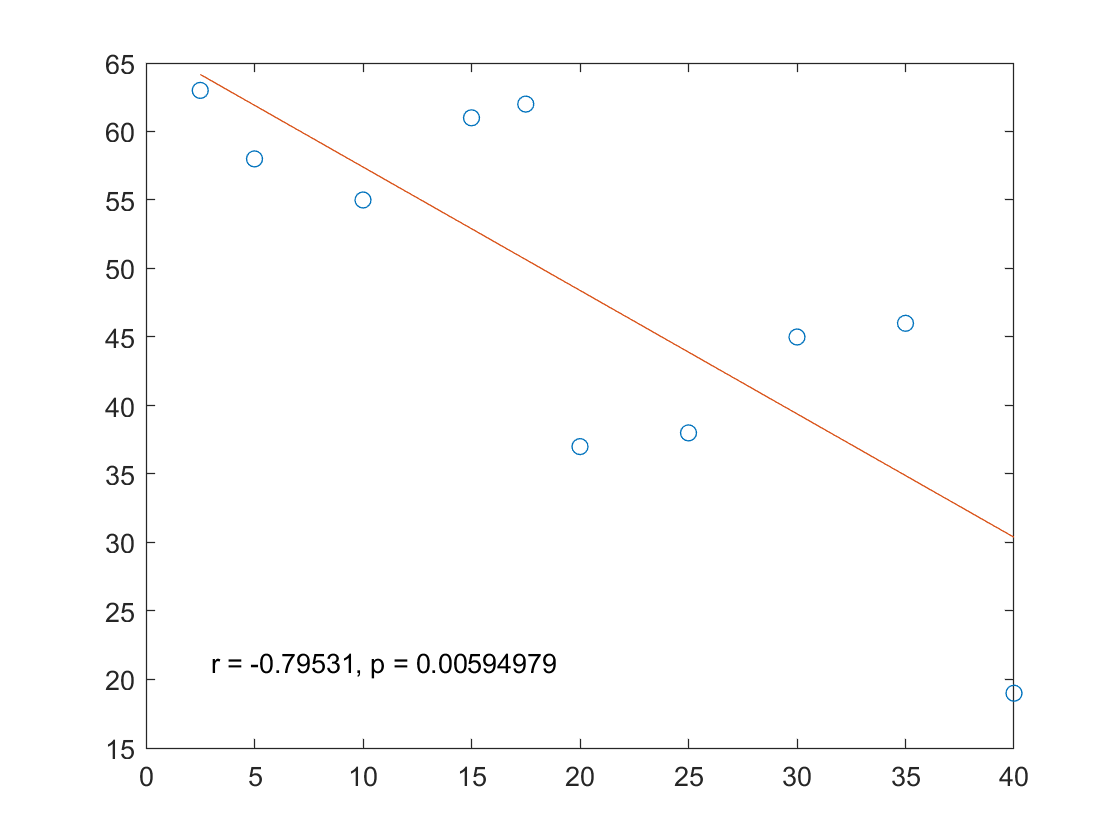

s = [2.5 5 10 15 17.5 20 25 30 35 40];
tf = [63 58 55 61 62 37 38 45 46 19];

pf = polyfit(s, tf, 1);
plot(s,tf,'o',s,polyval(pf,s));
[R, p] = corrcoef(s,tf);
text(3,20,sprintf('r = %g, p = %g\n',R(1,2),p(1,2)));

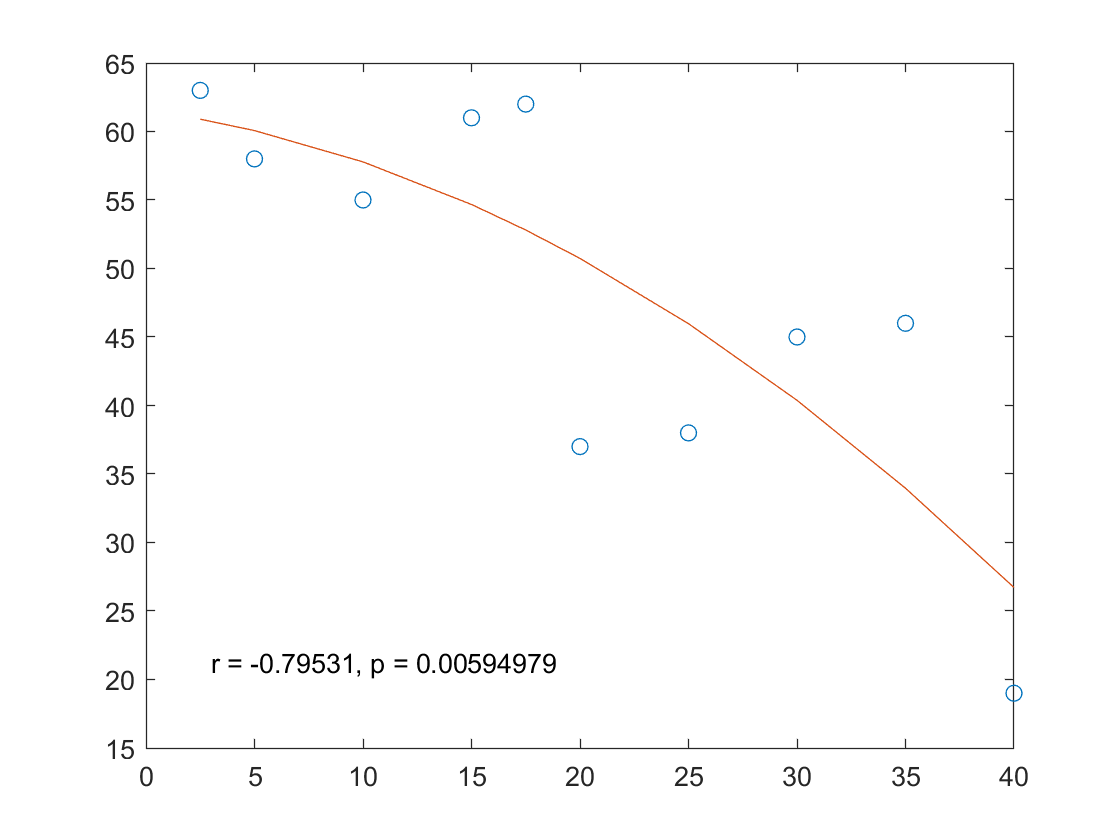


pf = polyfit(s, tf, 2);
plot(s,tf,'o',s,polyval(pf,s));
[R, p] = corrcoef(s,tf);
text(3,20,sprintf('r = %g, p = %g\n',R(1,2),p(1,2)));